#  Shallow-curved shell structure with geometric nonlinearities

Finite element model used in the following reference:

Jain, S., & Tiso, P. (2018). Simulation-free hyper-reduction for geometrically nonlinear structural dynamics: a quadratic manifold lifting approach. *Journal of Computational and Nonlinear Dynamics*, *13*(7), 071003. [https://doi.org/10.1115/1.4040021](https://doi.org/10.1115/1.4040021)

Finite element code taken from the following package:

Jain, S., Marconi, J., Tiso P. (2020). YetAnotherFEcode (Version v1.1). Zenodo. [http://doi.org/10.5281/zenodo.4011282](http://doi.org/10.5281/zenodo.4011282)

The shell is supported at the two opposite edges aligned along the y-axis, and we place 2 control forces at the Node A and Node B, respectively.

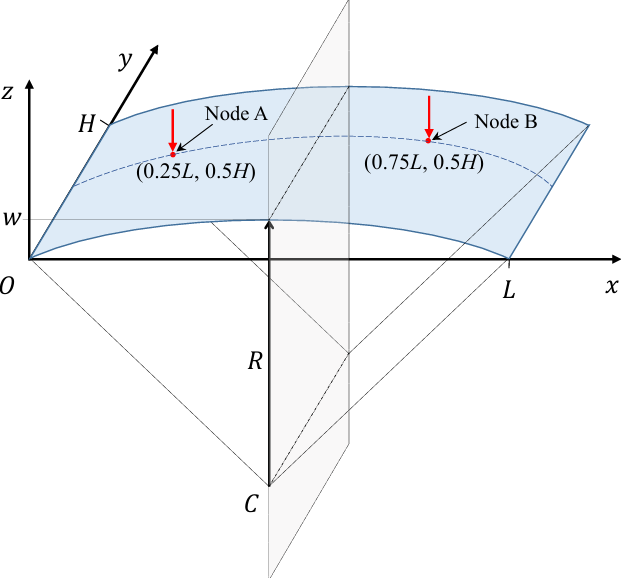

Here, we consider a 1:2 internal resonance between the first two bending modes of the shell to illustrate the wide applicability of our control design framework. 

**System parameters**

clear all
clc
nDiscretization = 10; % Discretization parameter (#DOFs is proportional to the square of this number)

## Model Setup

Building FE model


Assembling M,C,K matrices
Applying boundary conditions
Solving undamped eigenvalue problem


ans =   Patch (Deformed Mesh) - 属性:

    FaceColor: 'interp'
    FaceAlpha: 1
    EdgeColor: [0 0 0]
    LineStyle: '-'
        Faces: [400×3 double]
     Vertices: [1200×3 double]

  显示 所有属性

ans =   Patch (Deformed Mesh) - 属性:

    FaceColor: 'interp'
    FaceAlpha: 1
    EdgeColor: [0 0 0]
    LineStyle: '-'
        Faces: [400×3 double]
     Vertices: [1200×3 double]

  显示 所有属性

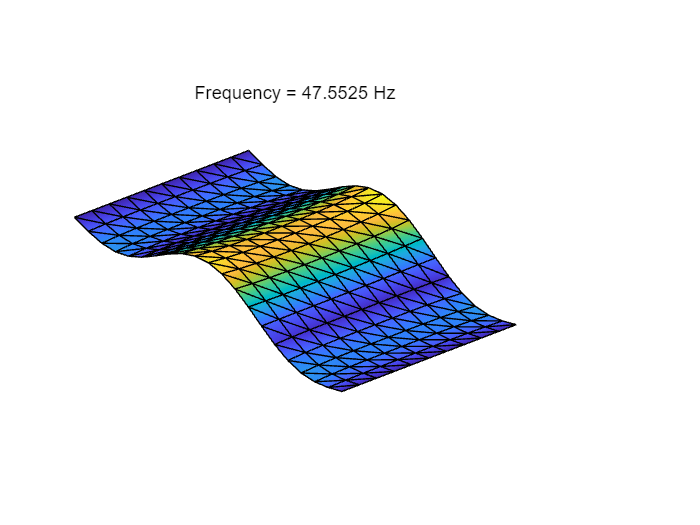

Using Rayleigh damping
Assembling external force vector
outnode
   171
outnode
    61
Getting nonlinearity coefficients
Loaded tensors from storage
Total time spent on model assembly = 00:00:11


[M,C,K,fnl,f_0,outdof] = build_model(nDiscretization);

n = length(M); % number of degrees of freedom
disp(['Number of degrees of freedom = ' num2str(n)])

Number of degrees of freedom = 1320


disp(['Phase space dimensionality = ' num2str(2*n)])

Phase space dimensionality = 2640


## Dynamical system setup 

We consider the forced system


$$\mathbf{M}\ddot{\mathbf{x}}+\mathbf{C}\dot{\mathbf{x}}+\mathbf{K}\mathbf{x}+\mathbf{f}(\mathbf{x},\dot{\mathbf{x}})=\epsilon\mathbf{f}^{ext}(\mathbf{\Omega}t),$$


which can be written in the first-order form as 


$$\mathbf{B}\dot{\mathbf{z}}	=\mathbf{Az}+\mathbf{F}(\mathbf{z})+\epsilon\mathbf{F}^{ext}(\mathbf{\phi}),\\\dot{\mathbf{\phi}}	
=\mathbf{\Omega}$$


where

$\mathbf{z}=\left[\begin{array}{c}\mathbf{x}\\\dot{\mathbf{x}}\end{array}\right],\quad\mathbf{A}=\left[\begin{array}{cc}-\mathbf{K} 
& \mathbf{0}\\\mathbf{0} & \mathbf{M}\end{array}\right],\mathbf{B}=\left[\begin{array}{cc}\mathbf{C} 
& \mathbf{M}\\\mathbf{M} & \mathbf{0}\end{array}\right],\quad\quad\mathbf{F}(\mathbf{z})=\left[\begin{array}{c}\mathbf{-\mathbf{f}(\mathbf{x},\dot{\mathbf{x}})}\\\mathbf{0}\end{array}\right],\quad\mathbf{F}^{ext}(\mathbf{z},\mathbf{\phi})=\left[\begin{array}{c}
\mathbf{f}^{ext}(\mathbf{\phi})\\
\mathbf{0}
\end{array}\right]$.

DS = DynamicalSystem();
set(DS,'M',M,'C',C,'K',K,'fnl',fnl);
set(DS.Options,'Emax',100,'Nmax',20,'notation','multiindex')

We assume that there is no external excitation but control inputs

Bext     = zeros(n,2); Bext(outdof(1),1)=1; Bext(outdof(2),2)=1; 
epsilon = 0.1; % converge at order 5
set(DS,'D',Bext,'epsilon',epsilon);
set(DS.Options, 'outDOF', outdof);

## Linear Modal analysis and SSM setup

[V,D,W] = DS.linear_spectral_analysis();

Due to high-dimensionality, we compute only the first 100 eigenvalues with the smallest magnitude. These would also be used to compute the spectral quotients
Assuming a proportional damping hypthesis with symmetric matrices
modal damping ratio for 1 mode is 2.000000e-03
modal damping ratio for 2 mode is 2.000000e-03
modal damping ratio for 3 mode is 2.102524e-03
modal damping ratio for 4 mode is 2.141338e-03
modal damping ratio for 5 mode is 2.369557e-03
modal damping ratio for 6 mode is 2.577829e-03
modal damping ratio for 7 mode is 2.839286e-03
modal damping ratio for 8 mode is 3.021625e-03
modal damping ratio for 9 mode is 3.198610e-03
modal damping ratio for 10 mode is 3.514516e-03
modal damping ratio for 11 mode is 3.909708e-03
modal damping ratio for 12 mode is 4.443252e-03
modal damping ratio for 13 mode is 4.804011e-03
modal damping ratio for 14 mode is 4.921314e-03
modal damping ratio for 15 mode is 5.018352e-03
modal damping ratio for 16 mode is 5.346229e-03
modal damping rat

## SSM Reduced dynamics - autonomous part

S = SSM(DS);
set(S.Options, 'reltol', 0.5,'IRtol',0.05,'notation', 'multiindex','contribNonAuto',true)
masterModes = [1,2,3,4]; 
S.choose_E(masterModes);

(near) outer resonance detected for the following combination of master eigenvalues
     2     0     0     0
     0     0     2     1
     1     1     1     0
     0     2     2     0
     2     0     1     1
     3     1     0     0
     0     0     3     2
     1     1     2     1
     2     2     1     0
     4     0     0     1
     0     2     3     1
     1     3     2     0
     2     0     2     2
     3     1     1     1
     4     2     0     0
     0     0     4     3
     0     4     3     0
     1     1     3     2
     2     2     2     1
     3     3     1     0
     4     0     1     2
     5     1     0     1
     0     2     4     2
     1     3     3     1
     2     0     3     3
     2     4     2     0
     3     1     2     2
     4     2     1     1
     5     3     0     0
     6     0     0     2
     0     0     5     4
     0     4     4     1
     1     1     4     3
     1     5     3     0
     2     2     3     2
     3     3     2     1
     4     0    

order = 3;
[W_0,R_0] = S.compute_whisker(order);

Due to (near) outer resonance, the exisitence of the manifold is questionable and the underlying computation may suffer.
Attempting manifold computation
Manifold computation time at order 2 = 00:00:00
Estimated memory usage at order  2 = 1.60E+01 MB
Manifold computation time at order 3 = 00:00:01
Estimated memory usage at order  3 = 2.10E+01 MB


auData = construct_autoData(DS, masterModes, R_0);   % use linear_spectral result 

## Linear model order reduction analysis

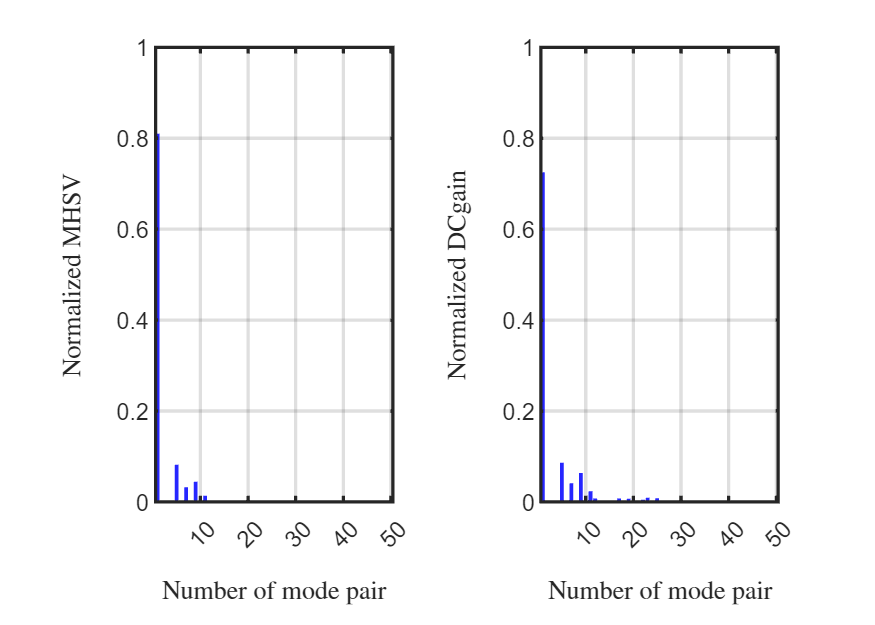

MHSV sum of the 1st,5th,7th,9th pairs
    0.9681
DCgain sum of the 1st,5th,7th,9th pairs
    0.9159


res = Linear_MOR(DS,50);

## Free Vibration

% initial condition
load("load400.mat","z0");
xf = z0';
z0 = xf';
tf     = 0.2; nsteps = 500;

t0 = 0; t1 =tf;
om = 2*pi/t1;
set(DS,'u',[]);
[tfullwo, xfullwo] = time_integration_transient(DS,om,'nCycles',...
    1, 'nSteps', nsteps,...
    'integrationMethod','Newmark','outdof',outdof,'init',z0);

Iteration 0, Residual norm = 0.99996
Iteration 1, Residual norm = 0.92165
Iteration 2, Residual norm = 0.085837
Iteration 3, Residual norm = 9.0147e-05
Iteration 4, Residual norm = 4.0372e-08
time integration completed: 0.2%
Iteration 0, Residual norm = 0.99996
Iteration 1, Residual norm = 0.87548
Iteration 2, Residual norm = 0.046854
Iteration 3, Residual norm = 3.7952e-05
time integration completed: 0.4%
Iteration 0, Residual norm = 0.99996
Iteration 1, Residual norm = 0.94234
Iteration 2, Residual norm = 0.078372
Iteration 3, Residual norm = 5.7971e-05
Iteration 4, Residual norm = 3.8232e-09
time integration completed: 0.6%
Iteration 0, Residual norm = 0.99996
Iteration 1, Residual norm = 0.90706
Iteration 2, Residual norm = 0.054767
Iteration 3, Residual norm = 6.4499e-05
Iteration 4, Residual norm = 7.6751e-10
time integration completed: 0.8%
Iteration 0, Residual norm = 0.99996
Iteration 1, Residual norm = 0.93727
Iteration 2, Residual norm = 0.049073
Iteration 3, Residual norm =

## Closed loop control with 3 receding horizons

**Time interval - 1**

% control parameters
cont   = struct();
cont.Q    = 3e4*eye(2*n,2*n);
cont.Rhat = 0.5*eye(2);
cont.Mhat = 2*eye(2*n); 

t0 = 0; t1 = 0.05;
tspan1 = linspace(t0,t1,nsteps);
traj1  = LQR_closed_loop(DS,z0,'linear',tspan1,auData,W_0,masterModes,[1:2,9:10,13:14,17:18],cont);

pl
  -0.1008 + 0.0002i
  -0.1008 - 0.0002i
   0.0168 - 0.0000i
   0.0168 + 0.0000i
p0
  -0.1008 + 0.0002i
  -0.1008 - 0.0002i
   0.0168 - 0.0000i
   0.0168 + 0.0000i
Time for backward simulation of Riccati ODE is 1.070049e-01
Time for backward simulation of compensated ODE is 1.189649e+00
历时 0.660808 秒。
Time for forward simulation of ODEs for modal coordinates is 6.694875e-01



ufun1 = @(t) transpose(interp1(traj1.time,traj1.ut',t,'linear','extrap'));
set(DS,'u',ufun1);
[tfull1, xfull1,x1f,xt1] = time_integration_transient(DS,2*pi/(t1-t0),'nCycles',...
    1, 'nSteps', nsteps,...
    'integrationMethod','Newmark','outdof',outdof,'init',z0);

Iteration 0, Residual norm = 0.99935
Iteration 1, Residual norm = 0.026269
Iteration 2, Residual norm = 6.9595e-07
time integration completed: 0.2%
Iteration 0, Residual norm = 0.99847
Iteration 1, Residual norm = 0.010866
Iteration 2, Residual norm = 1.8986e-07
time integration completed: 0.4%
Iteration 0, Residual norm = 0.99904
Iteration 1, Residual norm = 0.0064831
Iteration 2, Residual norm = 7.912e-08
time integration completed: 0.6%
Iteration 0, Residual norm = 0.99635
Iteration 1, Residual norm = 0.0032509
Iteration 2, Residual norm = 1.7671e-08
time integration completed: 0.8%
Iteration 0, Residual norm = 0.99614
Iteration 1, Residual norm = 0.0020398
Iteration 2, Residual norm = 6.8055e-09
time integration completed: 1%
Iteration 0, Residual norm = 0.9913
Iteration 1, Residual norm = 0.0013045
Iteration 2, Residual norm = 1.261e-09
time integration completed: 1.2%
Iteration 0, Residual norm = 0.99222
Iteration 1, Residual norm = 0.00045888
Iteration 2, Residual norm = 6.3841e

xf = x1f';

**Time interval - 2**

t2 = 0.1;
tspan2 = linspace(t1,t2,nsteps);
traj2  = LQR_closed_loop(DS,xf,'linear',tspan2,auData,W_0,masterModes,[1:2,9:10,13:14,17:18],cont);

pl
  -0.0091 - 0.0444i
  -0.0091 + 0.0444i
   0.0158 + 0.0244i
   0.0158 - 0.0244i
p0
  -0.0091 - 0.0444i
  -0.0091 + 0.0444i
   0.0158 + 0.0244i
   0.0158 - 0.0244i
Time for backward simulation of Riccati ODE is 6.043360e-02
Time for backward simulation of compensated ODE is 1.013093e+00
历时 0.533789 秒。
Time for forward simulation of ODEs for modal coordinates is 5.415342e-01


ufun2 = @(t) transpose(interp1(traj2.time,traj2.ut',t,'linear','extrap'));
set(DS,'u',ufun2);
[tfull2, xfull2,x2f,xt2] = time_integration_transient(DS,2*pi/(t2-t1),'nCycles',...
    1, 'nSteps', nsteps,...
    'integrationMethod','Newmark','outdof',outdof,'init',xf,'ts',t1);

Iteration 0, Residual norm = 0.59946
Iteration 1, Residual norm = 5.0223e-06
time integration completed: 50.1%
Iteration 0, Residual norm = 0.573
Iteration 1, Residual norm = 5.4336e-06
time integration completed: 50.2%
Iteration 0, Residual norm = 0.55713
Iteration 1, Residual norm = 3.9904e-06
time integration completed: 50.3%
Iteration 0, Residual norm = 0.53644
Iteration 1, Residual norm = 3.593e-06
time integration completed: 50.4%
Iteration 0, Residual norm = 0.54966
Iteration 1, Residual norm = 4.4162e-06
time integration completed: 50.5%
Iteration 0, Residual norm = 0.55432
Iteration 1, Residual norm = 4.2431e-06
time integration completed: 50.6%
Iteration 0, Residual norm = 0.54882
Iteration 1, Residual norm = 4.9193e-06
time integration completed: 50.7%
Iteration 0, Residual norm = 0.55254
Iteration 1, Residual norm = 4.7507e-06
time integration completed: 50.8%
Iteration 0, Residual norm = 0.55835
Iteration 1, Residual norm = 4.7129e-06
time integration completed: 50.9%
Iter

xf = x2f';

**Time interval - 3**

t3 = 0.2;
tspan3 = linspace(t2,t3,nsteps);
traj3  = LQR_closed_loop(DS,xf,'linear',tspan3,auData,W_0,masterModes,[1:2,9:10,13:14,17:18],cont);

pl
   0.0132 - 0.0026i
   0.0132 + 0.0026i
  -0.0277 - 0.0138i
  -0.0277 + 0.0138i
p0
   0.0132 - 0.0026i
   0.0132 + 0.0026i
  -0.0277 - 0.0138i
  -0.0277 + 0.0138i
Time for backward simulation of Riccati ODE is 7.195120e-02
Time for backward simulation of compensated ODE is 1.687588e+00
历时 1.517541 秒。
Time for forward simulation of ODEs for modal coordinates is 1.524787e+00


ufun3 = @(t) transpose(interp1(traj3.time,traj3.ut',t,'linear','extrap'));
set(DS,'u',ufun3);
[tfull3, xfull3,x3f,xt3] = time_integration_transient(DS,2*pi/(t3-t2),'nCycles',...
    1, 'nSteps', nsteps,...
    'integrationMethod','Newmark','outdof',outdof,'init',xf,'ts',t2);

Iteration 0, Residual norm = 0.7852
Iteration 1, Residual norm = 2.1824e-05
time integration completed: 50.1%
Iteration 0, Residual norm = 0.7803
Iteration 1, Residual norm = 2.5975e-05
time integration completed: 50.2%
Iteration 0, Residual norm = 0.75764
Iteration 1, Residual norm = 2.6699e-05
time integration completed: 50.3%
Iteration 0, Residual norm = 0.71045
Iteration 1, Residual norm = 3.308e-05
time integration completed: 50.4%
Iteration 0, Residual norm = 0.70973
Iteration 1, Residual norm = 3.0099e-05
time integration completed: 50.5%
Iteration 0, Residual norm = 0.64158
Iteration 1, Residual norm = 2.9857e-05
time integration completed: 50.6%
Iteration 0, Residual norm = 0.66214
Iteration 1, Residual norm = 3.5224e-05
time integration completed: 50.7%
Iteration 0, Residual norm = 0.59829
Iteration 1, Residual norm = 3.2703e-05
time integration completed: 50.8%
Iteration 0, Residual norm = 0.57639
Iteration 1, Residual norm = 3.2695e-05
time integration completed: 50.9%
Iter

**Plot - Node A**

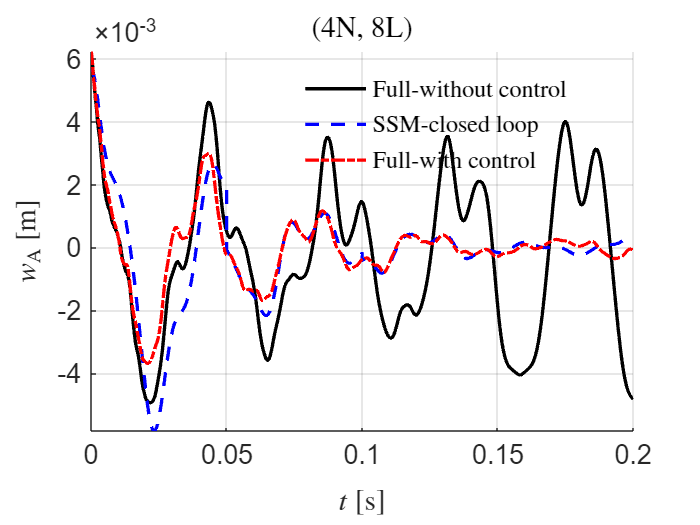

figure; hold on
plot(tfullwo, xfullwo(:,1),'k-','DisplayName', 'Full-without control','LineWidth',2);
plot([traj1.time, traj2.time, traj3.time], [traj1.zt(1,:),traj2.zt(1,:),traj3.zt(1,:)],'b--','DisplayName','SSM-closed loop','LineWidth',2);
plot([tfull1, tfull2, tfull3], [xfull1(:,1);xfull2(:,1);xfull3(:,1)],'r-.','DisplayName', 'Full-with control','LineWidth',2);
legend('show','Interpreter',"latex",Location="northeast"); legend boxoff
xlabel('$t$ [s]','Interpreter',"latex")
zk = strcat('$w_\mathrm{A}$ [m]');
ylabel(zk,'Interpreter','latex');
title('(4N, 8L)','Interpreter','latex')
set(gca,'FontSize',16);
grid on, axis tight
xlim([0,0.2])

**Plot- control inputs**

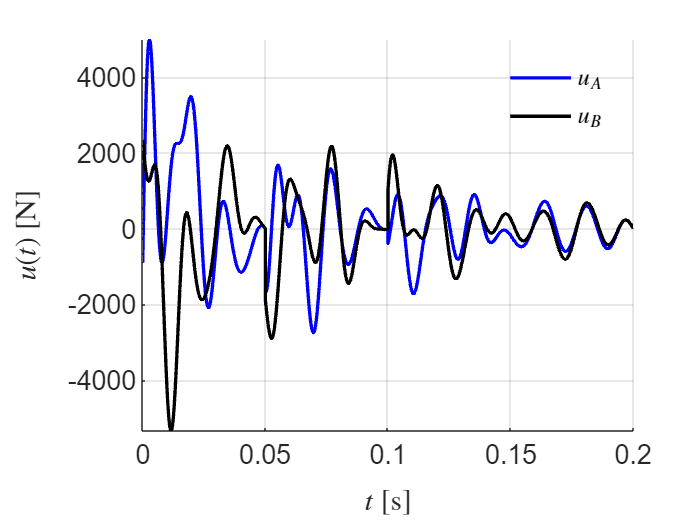

figure;hold on;
plot([traj1.time, traj2.time, traj3.time],[traj1.ut(1,:), traj2.ut(1,:), traj3.ut(1,:)],'b-','DisplayName', '$u_A$','LineWidth',2); 
plot([traj1.time, traj2.time, traj3.time],[traj1.ut(2,:), traj2.ut(2,:), traj3.ut(2,:)],'k-','DisplayName', '$u_B$','LineWidth',2);
legend('show','Interpreter',"latex"); legend boxoff
xlabel('$t$ [s]','Interpreter',"latex")
ylabel('$u(t)$ [N]','Interpreter','latex')
set(gca,'FontSize',16); grid on, axis tight